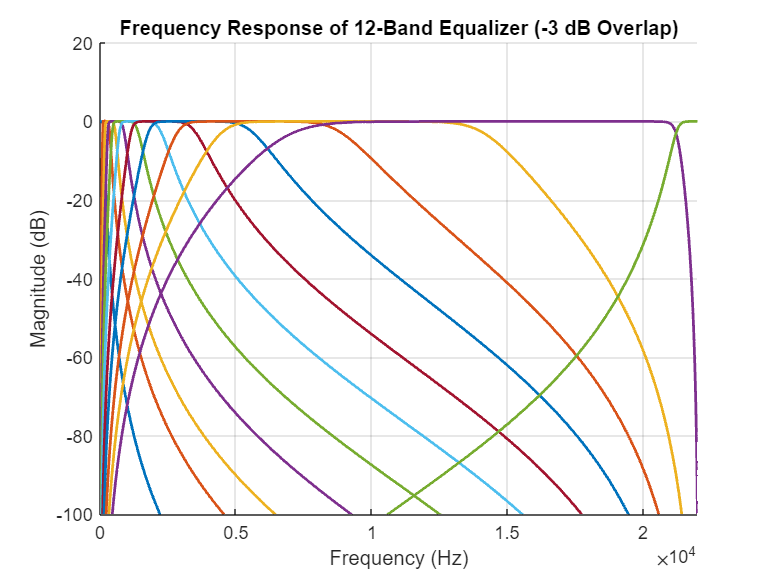

% Sampling frequency
fs = 44100;

% Band frequencies (in Hz)
%freqs = [0, 100, 300, 500, 700, 1000, 2000, 3000, 5000, 7000, 10000, 15000, fs/2];
freqs = [63, 125, 250, 400, 630, 1000, 1600, 2500, 4000, 6300, 10000, 15000, fs/2];

% Filter design
filters = cell(12, 1);

% Low-pass filter (first band)
[b, a] = butter(4, freqs(2) / (fs / 2), 'low');
filters{1} = {b, a};

% Band-pass filters (bands 2 to 11)
for i = 2:11
    % Adjust cutoff frequencies for -3 dB overlap
    lower_cutoff = freqs(i) / sqrt(2);
    upper_cutoff = freqs(i+1) * sqrt(2); 
    
    % Normalize to Nyquist and ensure values are valid (between 0 and 1)
    lower_cutoff = max(lower_cutoff / (fs / 2), 0); % Clamp to >= 0
    upper_cutoff = min(upper_cutoff / (fs / 2), 1); % Clamp to <= 1
    
    % Skip invalid band if cutoff frequencies are out of range
    if lower_cutoff >= upper_cutoff
        warning('Invalid cutoff frequencies for band %d: Skipping.', i);
        continue;
    end

    % Design band-pass filter
    [b, a] = butter(4, [lower_cutoff, upper_cutoff], 'bandpass');
    filters{i} = {b, a};
end

% High-pass filter (last band)
[b, a] = butter(4, freqs(end-1) * sqrt(2) / (fs / 2), 'high');
filters{12} = {b, a};

% Plot the frequency response of the filters
figure;
hold on;
for i = 1:12
    if isempty(filters{i})
        continue; % Skip if the filter was invalid
    end
    [h, f] = freqz(filters{i}{1}, filters{i}{2}, 1024, fs);
    plot(f, 20*log10(abs(h)), 'DisplayName', sprintf('Band %d', i), 'LineWidth', 1.5);
end

title('Frequency Response of 12-Band Equalizer (-3 dB Overlap)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
ylim([-100 20])
xlim([0 22000])
%legend('show');
grid on;